# 5.5 FIR 的频率采样型结构：梳状滤波器 × 谐振器、零极点对消、r 略小于 1 的修正、合并成实系数二阶节

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 系统：教材习题 8 的频率采样值，N=16：H(0)=12，H(1)=−3−j3，H(2)=1+j，H(14)=1−j，H(15)=−3+j3，其余为 0

N = 16; Hk = zeros(1, N); Hk(1) = 12; Hk(2) = -3-3i; Hk(3) = 1+1i; Hk(15) = 1-1i; Hk(16) = -3+3i;
hDirect = ifft(Hk); assert(max(abs(imag(hDirect))) < 1e-12); hDirect = real(hDirect);   % H(k) 共轭对称 → h(n) 为实
kUsed = find(Hk ~= 0) - 1;                        % [0 1 2 14 15]

## 演示1：梳状滤波器 1 − z^{-N}：N 个零点均匀分布在单位圆上，|H(e^{jω})| = 2|sin(Nω/2)|（教材图 5.3.8）

w = linspace(0, pi, 2048); Hcomb = 1 - exp(-1i*w*N);
zComb = exp(2i*pi*(0:N-1)/N);

## 演示2：谐振器 H(k)/(1 − W_N^{-k} z^{-1})：极点 z_k = e^{j2πk/N} 正好落在梳状滤波器的零点上——零极点对消（教材图 5.3.9）

pRes = exp(2i*pi*kUsed/N);

## 演示3：频率采样结构（教材式 (5.3.6)）：复数谐振器并联，r=1 与 r=0.99，和直接型 h(n) 逐点比较

L = 1000; delta = [1 zeros(1, L-1)];                % 看到 n=1000，r=0.99 的残余（∝0.99^n）才衰减到可忽略
hFS1 = freq_sampling(Hk, 1, delta);
errFS1 = max(abs(hFS1(1:N) - hDirect)); tailFS1 = max(abs(hFS1(N+1:end)));
r = 0.99; hFS99 = freq_sampling(Hk, r, delta);
errFS99 = max(abs(hFS99(1:N) - hDirect .* r.^(0:N-1)));   % r<1 时严格等于 h(n)·r^n（教材式 (5.3.7) 的 Hr(k)≈H(k)）
tailFS99 = max(abs(hFS99(N+1:end)));

## 演示4：合并共轭对为实系数二阶节（教材式 (5.3.10)—(5.3.12)）；系数舍入后 r=1 与 r<1 的差别

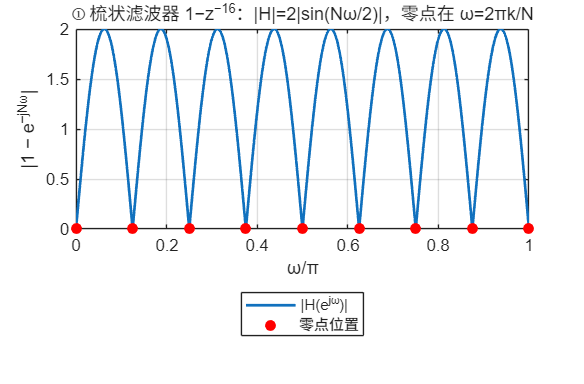

hR1 = freq_sampling_real(Hk, 1, delta, Inf); errR1 = max(abs(hR1(1:N) - hDirect));
Bq = 10;                                          % 所有分子、分母系数舍入到 2^-10
hQ1 = freq_sampling_real(Hk, 1, delta, Bq); hQ99 = freq_sampling_real(Hk, 0.99, delta, Bq);
tailQ1 = abs(hQ1(N+1:end)); tailQ99 = abs(hQ99(N+1:end));   % 理想情况 n≥N 应为 0；舍入后对消不完全，留下的“尾巴”
tailEndQ1 = max(tailQ1(end-49:end)); tailEndQ99 = max(tailQ99(end-49:end));   % 末 50 点

if ~LIVE, f1 = figure('Name','05 频率采样结构','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(w/pi, abs(Hcomb), 'LineWidth', 1.6); hold on;
kk = 0:N/2; plot(2*kk/N, zeros(size(kk)), 'ro', 'MarkerFaceColor', 'r');
grid on; xlabel('ω/π'); ylabel('|1 − e^{−jNω}|'); title(sprintf('① 梳状滤波器 1−z^{−%d}：|H|=2|sin(Nω/2)|，零点在 ω=2πk/N', N));
legend('|H(e^{jω})|', '零点位置');

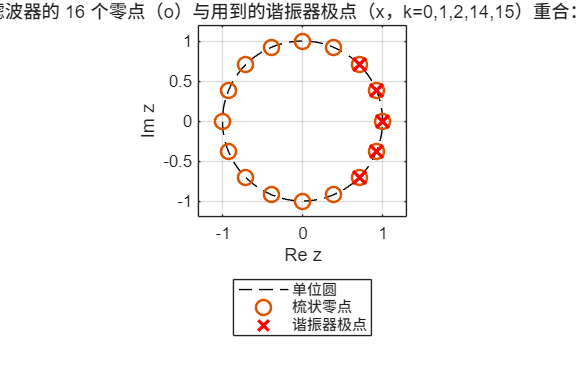

newpanel(); tt = linspace(0, 2*pi, 400); plot(cos(tt), sin(tt), 'k--'); hold on; axis equal; grid on;
plot(real(zComb), imag(zComb), 'o', 'MarkerSize', 9, 'LineWidth', 1.5);
plot(real(pRes), imag(pRes), 'rx', 'MarkerSize', 11, 'LineWidth', 2);
xlim([-1.3 1.3]); ylim([-1.2 1.2]); xlabel('Re z'); ylabel('Im z');
title(sprintf('② 梳状滤波器的 %d 个零点（o）与用到的谐振器极点（x，k=%s）重合：零极点对消', N, strjoin(compose('%d', kUsed), ',')));
legend('单位圆', '梳状零点', '谐振器极点');

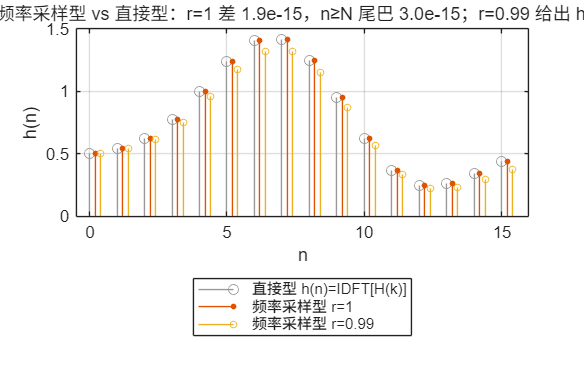

newpanel(); stem(0:N-1, hDirect, 'MarkerSize', 6, 'Color', [0.6 0.6 0.6]); hold on;
stem((0:N-1)+0.2, hFS1(1:N), 'filled', 'MarkerSize', 3); stem((0:N-1)+0.4, hFS99(1:N), 'MarkerSize', 4);
grid on; xlim([-0.5 N]); xlabel('n'); ylabel('h(n)');
title(sprintf('③ 频率采样型 vs 直接型：r=1 差 %.1e，n≥N 尾巴 %.1e；r=0.99 给出 h(n)·r^n', errFS1, tailFS1));
legend('直接型 h(n)=IDFT[H(k)]', '频率采样型 r=1', '频率采样型 r=0.99');

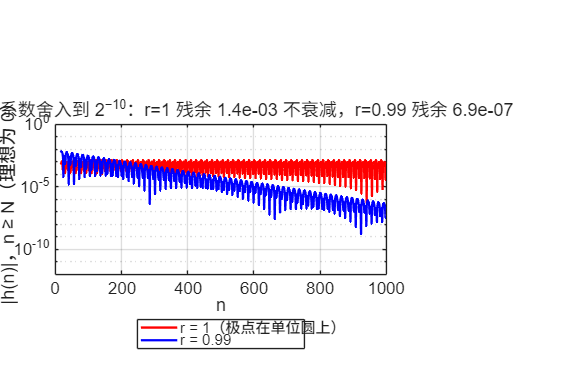

newpanel(); semilogy(N:L-1, max(tailQ1, 1e-18), 'r-', 'LineWidth', 1.4); hold on; semilogy(N:L-1, max(tailQ99, 1e-18), 'b-', 'LineWidth', 1.4);
grid on; xlabel('n'); ylabel('|h(n)|，n ≥ N（理想为 0）'); ylim([1e-12 1]);
title(sprintf('④ 二阶节系数舍入到 2^{−%d}：r=1 残余 %.1e 不衰减，r=0.99 残余 %.1e', Bq, tailEndQ1, tailEndQ99));
legend('r = 1（极点在单位圆上）', 'r = 0.99');

if ~LIVE, sgtitle('频率采样结构：用 IIR 的零极点对消实现 FIR；理论上精确，工程上要把 r 取得略小于 1'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '05-frequency-sampling.png'), 'Resolution', 150); end

## 教师核验

assert(errFS1 < 1e-12 && errFS99 < 1e-12 && errR1 < 1e-12, '频率采样结构应与直接型逐点一致');
assert(tailFS1 < 1e-12, '浮点下 r=1 的尾巴应可忽略');
assert(tailEndQ99 < tailEndQ1/100, '系数舍入后 r<1 的尾巴应远小于 r=1');
assert(max(abs(pRes - zComb(kUsed+1))) < 1e-12, '谐振器极点应与梳状零点重合');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'N', N, 'k_used', kUsed, 'h_direct', hDirect, 'err_fs_r1', errFS1, 'tail_fs_r1', tailFS1, 'err_fs_r099_vs_h_rn', errFS99, 'tail_fs_r099', tailFS99, ...
    'err_real_sections_r1', errR1, 'quant_bits', Bq, 'tail_end_quantized_r1', tailEndQ1, 'tail_end_quantized_r099', tailEndQ99, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-frequency-sampling.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

             matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                     run_at: '2026-09-18 20:50:23'
                          N: 16
                     k_used: [0 1 2 14 15]
                   h_direct: [0.5000 0.5471 0.6250 0.7762 1 1.2400 1.4053 1.4167 1.2500 0.9529 0.6250 0.3703 0.2500 0.2600 0.3447 0.4368]
                  err_fs_r1: 1.8874e-15
                 tail_fs_r1: 2.9661e-15
        err_fs_r099_vs_h_rn: 1.6653e-15
               tail_fs_r099: 2.4581e-15
       err_real_sections_r1: 4.4409e-16
                 quant_bits: 10
      tail_end_quantized_r1: 0.0014
    tail_end_quantized_r099: 6.9281e-07
          all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results


## 本地函数

function y = freq_sampling(Hk, r, x)
% 教材式 (5.3.6)/(5.3.7)：H(z) = (1 − r^N z^{-N})/N · Σ_k H(k)/(1 − r W_N^{-k} z^{-1})，复数谐振器逐个并联
N = numel(Hk); v = filter([1 zeros(1, N-1) -r^N], 1, x);          % 梳状滤波器
y = zeros(size(x));
for k = find(Hk ~= 0) - 1
    y = y + filter(Hk(k+1), [1 -r*exp(2i*pi*k/N)], v);            % 谐振器：极点 r·W_N^{-k}
end
y = real(y)/N;
end

function y = freq_sampling_real(Hk, r, x, Bq)
% 教材式 (5.3.10)—(5.3.12)：k 与 N−k 的谐振器合并成实系数二阶节；k=0（和 N/2）为一阶节。Bq=Inf 不量化
N = numel(Hk); if isinf(Bq), q = @(c) c; else, q = @(c) round(c*2^Bq)/2^Bq; end
v = filter(q([1 zeros(1, N-1) -r^N]), 1, x);
y = filter(q(real(Hk(1))), q([1 -r]), v);                          % H_0(z)=H(0)/(1 − r z^{-1})
if mod(N, 2) == 0 && Hk(N/2+1) ~= 0, y = y + filter(q(real(Hk(N/2+1))), q([1 r]), v); end   % H_{N/2}(z)
for k = 1:ceil(N/2)-1
    if Hk(k+1) == 0, continue; end
    mag = abs(Hk(k+1)); th = angle(Hk(k+1)); wk = 2*pi*k/N;
    num = 2*mag*[cos(th), -r*cos(th - wk)];                        % 2|H(k)|[cosθ(k) − r z^{-1} cos(θ(k) − 2πk/N)]
    den = [1, -2*r*cos(wk), r^2];                                  % 1 − 2r cos(2πk/N) z^{-1} + r^2 z^{-2}
    y = y + filter(q(num), q(den), v);
end
y = y/N;
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end